%% ============================================================
%  Wearable Loop Antenna SAR – Fixed & Stable
%  Frequency: 13.56 MHz
%  Antenna offset: 1 cm from arm
% ============================================================

clc; close all; clear;

%% ---------------- Constants ----------------
f     = 13.56e6;
omega = 2*pi*f;
mu0   = 4*pi*1e-7;

%% ---------------- FIXED DRIVE (NO RADIATION MODEL) ----------
I_rms = 0.4;                 % <-- FIXED sane NFC current
Ipk  = I_rms*sqrt(2);

%% ---------------- Tissue (muscle) ----------------
sigma = 0.7;                 % S/m
rho   = 1000;                % kg/m^3

%% ---------------- Arm geometry ----------------
arm_radius = 40e-3;          % 40 mm
arm_length = 220e-3;

%% ---------------- Loop geometry ----------------
R = 18.5e-3;
lead_len = 20e-3;
gap_half = 10;
N_arc = 240;
N_lead = 50;

antenna_offset = arm_radius + 10e-3;

%% ---------------- Build loop ----------------
arc_start = 270 + gap_half;
arc_end   = 270 - gap_half + 360;

phi = linspace(arc_start,arc_end,N_arc+1)*pi/180;
phi(end) = [];

arc_x = R*cos(phi);
arc_y = R*sin(phi) + antenna_offset;
arc_z = zeros(size(phi));

P1 = [arc_x(1) arc_y(1)];
P2 = [arc_x(end) arc_y(end)];
d1 = P1/norm(P1);
d2 = P2/norm(P2);

t = linspace(0,1,N_lead+1); t(end)=[];

lead1_x = P1(1) + lead_len*(1-t)*d1(1);
lead1_y = P1(2) + lead_len*(1-t)*d1(2);
lead2_x = P2(1) + lead_len*t*d2(1);
lead2_y = P2(2) + lead_len*t*d2(2);

Wx = [lead1_x arc_x lead2_x];
Wy = [lead1_y arc_y lead2_y];
Wz = zeros(size(Wx));

Sx = 0.5*(Wx(1:end-1)+Wx(2:end));
Sy = 0.5*(Wy(1:end-1)+Wy(2:end));
Sz = zeros(size(Sx));

dLx = diff(Wx);
dLy = diff(Wy);
dLz = zeros(size(dLx));

%% ---------------- Observation grid ----------------
Nx = 120; Ny = 120; Nz = 100;

xv = linspace(-60e-3,60e-3,Nx);
yv = linspace(-60e-3,60e-3,Ny);
zv = linspace(-arm_length/2,arm_length/2,Nz);

[X,Y,Z] = meshgrid(xv,yv,zv);
Rxy = sqrt(X.^2 + Y.^2);
inside_arm = Rxy <= arm_radius;

%% ---------------- B FIELD (quasi-static) ----------------
Bx = zeros(size(X)); By = Bx; Bz = Bx;

for m = 1:length(Sx)
    rx = X - Sx(m);
    ry = Y - Sy(m);
    rz = Z;
    r  = sqrt(rx.^2 + ry.^2 + rz.^2);
    r(r<1e-9)=1e-9;

    rxh = rx./r; ryh = ry./r; rzh = rz./r;

    cx = dLy(m).*rzh - dLz(m).*ryh;
    cy = dLz(m).*rxh - dLx(m).*rzh;
    cz = dLx(m).*ryh - dLy(m).*rxh;

    coeff = (mu0*Ipk)/(4*pi*r.^2);

    Bx = Bx + coeff .* cx;
    By = By + coeff .* cy;
    Bz = Bz + coeff .* cz;
end

Bmag = sqrt(Bx.^2 + By.^2 + Bz.^2)/sqrt(2);

%% ---------------- E FIELD ESTIMATE ----------------
Leff = sqrt(X.^2 + Y.^2 + Z.^2);
E = omega .* Leff .* Bmag;

%% ---------------- SAR ----------------
SAR = zeros(size(E));
SAR(inside_arm) = sigma .* E(inside_arm).^2 ./ (2*rho);

fprintf('Max SAR = %.3f W/kg\n', max(SAR(:)));

Max SAR = 20.728 W/kg


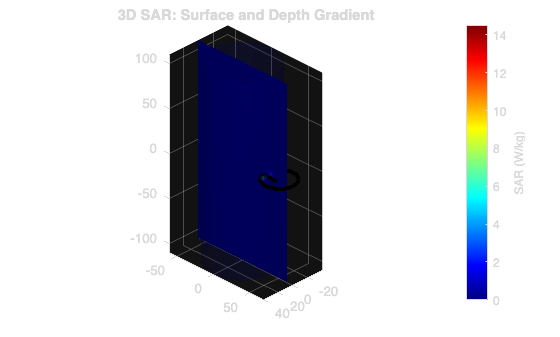


%% ==================== IMPROVED 3D VISUALIZATION =====================
% Explicitly set the renderer for Mac stability
set(gcf, 'Renderer', 'opengl');

% 1. Higher Resolution Cylinder Mesh for the Skin
theta = linspace(0, 2*pi, 120);
z_cyl = linspace(-arm_length/2, arm_length/2, 100);
[TH, Zs] = meshgrid(theta, z_cyl);
Xs = arm_radius * cos(TH);
Ys = arm_radius * sin(TH);

% Map SAR to this surface
SAR_skin = interp3(X, Y, Z, SAR, Xs, Ys, Zs, 'linear', 0);

% 2. Plotting
figure('Color', 'w');
% Transparent Skin
s = surf(Xs*1e3, Ys*1e3, Zs*1e3, SAR_skin, 'EdgeColor', 'none', 'FaceAlpha', 0.2);
hold on;

% 3. The "Gradient In" Slice (Sagittal Plane at X=0)
% This cuts right through the antenna into the arm
h = slice(X*1e3, Y*1e3, Z*1e3, SAR, 0, [], []);
set(h, 'EdgeColor', 'none', 'FaceAlpha', 1.0); % Opaque slice to see gradient

% 4. Antenna (offset for visibility)
plot3(Wx*1e3, Wy*1e3, Wz*1e3, 'k', 'LineWidth', 3);

% 5. Professional Styling
colormap(jet); % Or hot, depending on preference
c = colorbar;
c.Label.String = 'SAR (W/kg)';

% Adjust color limits to make the gradient "pop"
maxSAR = max(SAR(:));
clim([0, maxSAR * 0.7]); % Saturate the scale slightly

axis equal tight;
view(135, 30); % Angled view to see both surface and slice
camlight headlight; 
lighting gouraud;
title('3D SAR: Surface and Depth Gradient');